# MATLAB Job Submission

[<< Index](matlab:open('../MATLAB_Parallel_Computing_Workshop.mlx'))

This example shows how to submit a MATLAB job on a cluster.

To execute each section in this script you can either click on 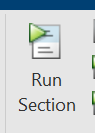, or click on the blue bar on the left of the section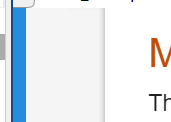.

**Note**: Run the sections sequentially to prevent errors.

#### Introduction

We can use `batch` jobs to offload the execution of long-running computations in the background and carry out other tasks while the batch job is processing. `batch` does not block MATLAB and we can continue working while computations take place. When we submit batch jobs to another computer or cluster, we can even close MATLAB on the client, and retrieve results later.

In this exercise, we will submit batch jobs from MATLAB to our local machine. The workers will run on the same machine as the client, but the same workflow can be used to submit jobs to a remote compute cluster or the cloud, freeing up our local resources.

#### Documentation and Examples

- [Get Started with Parallel Computing Toolbox](https://www.mathworks.com/help/parallel-computing/getting-started-with-parallel-computing-toolbox.html)

- [Run MATLAB Functions on a GPU](https://www.mathworks.com/help/parallel-computing/run-matlab-functions-on-a-gpu.html)

- [Choose Between spmd, parfor, and parfeval - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/parallel-computing/choose-spmd-parfor-parfeval.html)

#### **Job Submission**

In this example, the code being executed approximates the value of Pi using a [Monte Carlo method](https://en.wikipedia.org/wiki/Monte_Carlo_method). See the Job Submission section and the call to the `@computePi` function. The code that approximates pi is written in the Write Your Own Function section. You can write your own MATLAB function here and then test it. If you change the function name, remember to change it in the [`batch`](https://www.mathworks.com/help/parallel-computing/batch.html) function as well.

c = parcluster('ClusterRecherche');
NUM_WORKERS = 32;
job = batch(c,@computePI,1,{10e4,10e4},Pool=NUM_WORKERS,AutoAddClientPath=false,CurrentFolder='.');

Besides the `numWorkers` used to evaluate the loop iterations, an additional worker runs the serial code. Thus, `numWorkers`+1 workers are used on the cluster.

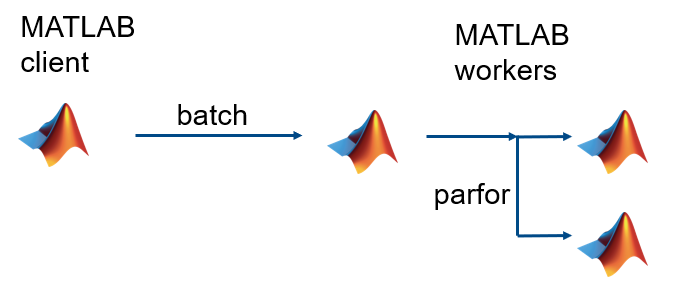

**Monitor your job**

To monitor your job you can click on Home and then on Parallel (Icon with 4 blue bars) then choose Monitor Jobs.

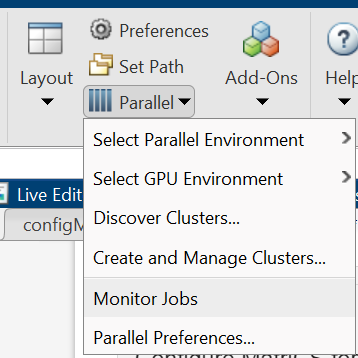

Right-click on any job in the list, and select any of the following options from the context menu. The available options depend on the type of job.

- **Cancel** — Stops a running job and changes its state to `'finished'`. If the job is pending or queued, the state changes to `'finished'` without its ever running. This is the same as the command-line [`cancel`](https://www.mathworks.com/help/parallel-computing/parallel.task.cancel.html) function for the job.

- **Delete** — Deletes the job data and removes the job from the queue. This is the same as the command-line [`delete`](https://www.mathworks.com/help/parallel-computing/parallel.job.delete.html) function for the job. Also closes and deletes an interactive pool job.

- **Show Details** — This displays detailed information about the job in the Command Window.

- **Show Errors** — This displays all the tasks that generated an error in that job, with their error properties.

- **Fetch Outputs** — This collects all the task output arguments from the job into the client workspace.

When the job completes, retrieve the results interactively.

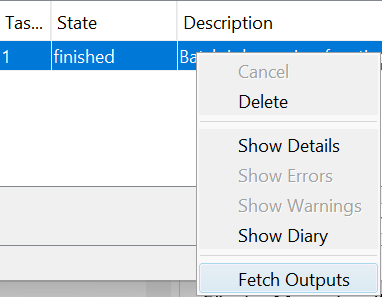

You can also just display the variable `job`

job

or

c.Jobs

#### Get the result

If the job has completed successfully, you should see the estimated value of pi displayed, approximately 3.14.

if job.State == "finished"
    results = job.fetchOutputs
else
   disp(['Job state: ', job.State]);
end

#### **Compute PI with Monte Carlo Method**

You can estimate the value of π using a variety of Monte Carlo methods. This example shows how to estimate π with the simple Monte Carlo area method. 

To estimate π with the Monte Carlo Area method, you perform these steps: 

- Randomly generate $x$ and $y$ coordinates of a point from a uniform distribution. 

- Determine whether the point is inside a circle inscribed in a square. Update the number of points in the circle and total number of points. 

- Repeat as needed to refine the estimate.

function PI = computePI(m,n)
    tic
    c = 0;
    parfor i = 1:n
        x = rand(m,1);
        y = rand(m,1);
        r = x.^2 + y.^2;
        c = c + sum(r<=1);
    end
    PI = 4/(m*n) * c;
    toc
end

#### Write Your Own Function

Now to you: write your function and modify the batch command to call your function.

function out = myFunction(in)
    out = in;
end